# This is the live script for ESE 6190 HW4 MPC Theory I problem 12

clear all
clc

% Define system matrics
A = [cos(0.5), -sin(0.5); sin(0.5), cos(0.5)];
B = eye(2);
xmax = 10;
xmin = -10;
umax = 5;
umin = -5;
% check the corner points for k1, k2
vertices = [[xmax;xmax],[xmax;xmin],[xmin;xmax],[xmin;xmin]];
% write the inequality constriants, using MPT toolboX
k = sdpvar(2, 1);
eq_x = (A+B*diag(k))*vertices;
eq_u = diag(k)*vertices;
constraints = [-10<=reshape(eq_x,8,1)<=10; -5<=reshape(eq_u,8,1)<=5];
S = YSet(k, constraints);
Boundary = S.outerApprox();
k_lb = Boundary.Internal.lb

k_lb =    -0.5000
   -0.5000


k_ub = Boundary.Internal.ub

k_ub =    -0.3570
   -0.3570


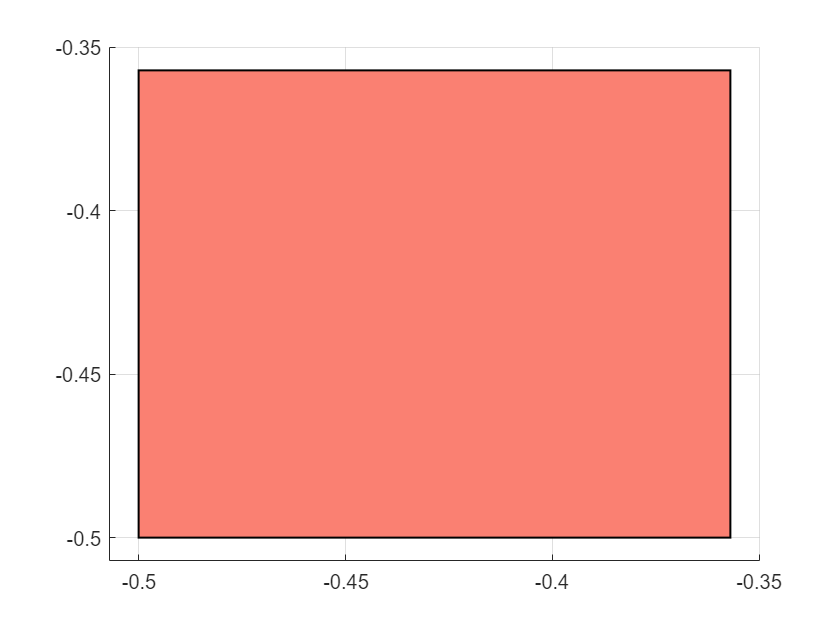

S.plot('color', 'salmon')